%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader-substrate mismatch position on DNA/DNA
%toehold exchange kinetics including spontaneous incumbent and invader
%dissociation

b = 20 %define branch migration domain length

b = 20

g = 6 %define invader toehold length

g = 6

g2 = 2 %define incumbent toehold length

g2 = 2


bg2 = b + g2 %define branch migration domain + incumbent toehold length

bg2 = 22


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 20)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch positions 
for m = 1:20
    m
    trans_state = - dGbp *(b+ g-1)
    react_coord = zeros(1, b-1)
    %loop through states after mismatch and define free energy (in terms of
    %dissociation)
    for state = 1:b-m
        react_coord(state) = -dGbp*(state) + dGmm
    end
    %loop states before mismatch and define free energy (in terms of
    %dissociation)
    for state = b-m+1:b-1
        react_coord(state) = - dGbp*(state)
    end

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_Crm = k_bp * exp((dGmm - dGbm)/(R*temp))
    k_Crm_end = k_bp * exp((dGmm - dGbm - dGp)/(R*temp))
    k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp * exp(dGbp/(R*temp));
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        
    %define spontaneous invader dissociation rates for mismatch-free system
    Koff_inv_perf = [repmat(0, [1, g2+1])];
    for n = b+g-1:-1:g+1
            Koff_inv_perf = horzcat(Koff_inv_perf, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
    end
    Koff_inv_perf = horzcat(Koff_inv_perf, [repmat(0, [1, g+1])])        
        
         
    if m == b
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(b+g2-m+1) = k_Crm_end
        
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2 + 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
        %define spontaneous invader dissociation rates for mismatch system
        Koff_inv = [repmat(0, [1, g2+1])];
        for n = 1:b-1
            Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(-dGbp)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))])
        end
        Koff_inv = horzcat(Koff_inv, [repmat(0, [1, g+1])])
        
    else
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(b + g2 - m + 1) = k_Crm
        
        %define spontaneous incumbent dissociation rates 
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2 + 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
        %define spontaneous invader dissociation rates for mismatch system
        Koff_inv = [repmat(0, [1, g2+1])];
        for n = 1:b-1
            Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(-dGbp)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff_inv = horzcat(Koff_inv, [repmat(0, [1, g+1])])
        
        
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    j_cycle = zeros(1,numel(Kf));
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + (Koff(Pn) + Koff_inv(Pn)) * Pn_jN_1(Pn);
        j_cycle(Pn) = Pn_jN_1(Pn)*Koff_inv(Pn);
    end
    
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    j_cycle_perf = zeros(1,numel(Kf_perf));
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
    
    %calculate flux between each state for mismatch-free system    
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf(Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + (Koff(Pn) + Koff_inv_perf(Pn)) * Pn_jN_1_perf(Pn);
        j_cycle_perf(Pn) = Pn_jN_1_perf(Pn)*Koff_inv_perf(Pn);
    end
        
    j_disp = jn_jN_1(end-1) - sum(j_cycle(1:end)) %successful flux for mismatch system
    first_pass_time (m) = (1/j_disp)*sum(Pn_jN_1) %first passage time for mismatch system
    %first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1)
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8)); %effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1)%probability of being in unbound state for mismatch system
    
    j_disp_perf = jn_jN_1_perf(end-1) - sum(j_cycle_perf(1:end)) %successful flux for mismatch-free system
    first_pass_time_perf (m) = (1/j_disp_perf)*sum(Pn_jN_1_perf)%first passage time for mismatch-free system
    %first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf)
    k_eff_perf(m) = 1/(first_pass_time_perf(m)*(5*10^-8));%effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf)%probability of being in unbound state for mismatch-free system
    
end

m = 1

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   31.0075         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   31.0075   32.5004         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   31.0075   32.5004   33.9933


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv = 	1.0e+04 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0102    0.1267    1.5748         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time = 	1.0e+04 *

    2.1080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 2

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   31.0075         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   31.0075   32.5004         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   31.0075   32.5004   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0007    0.0082    0.1020    1.2671    0.0012         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 3

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   31.0075         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   31.0075   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   31.0075   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0043    0.0531    0.6600    8.2030  101.9512    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190    1.8035         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 4

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   29.5146   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0043    0.0531    0.6600    8.2030    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190    1.8035    1.6935         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 5

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   28.0217   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0043    0.0531    0.6600    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 6

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   26.5287   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0043    0.0531    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 7

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   25.0358   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0043    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 8

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   23.5429   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0         0


m = 9

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   22.0500   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0         0


m = 10

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   20.5571   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0         0


m = 11

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   19.0642   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0810

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818         0         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0         0


m = 12

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   17.5713   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0813

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242    0.8139         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818    0.9814         0         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0         0


m = 13

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   16.0784   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.0845

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242    0.8139    0.7025         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818    0.9814    0.9811         0         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0         0


m = 14

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926   14.5855   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.1184

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242    0.8139    0.7025    0.5828         0         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818    0.9814    0.9811    0.9807         0         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0         0


m = 15

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997   13.0926    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.4594

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242    0.8139    0.7025    0.5828    0.4087         0         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818    0.9814    0.9811    0.9807    0.9804         0         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0         0


m = 16

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068   11.5997    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 5.7051

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242    0.8139    0.7025    0.5828    0.4087    0.1362         0         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818    0.9814    0.9811    0.9807    0.9804    0.9800         0         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0         0


m = 17

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138   10.1068    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 33.7284

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242    0.8139    0.7025    0.5828    0.4087    0.1362    0.0168         0         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818    0.9814    0.9811    0.9807    0.9804    0.9800    0.9803         0         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0         0


m = 18

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    8.6138    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 231.1839

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242    0.8139    0.7025    0.5828    0.4087    0.1362    0.0168    0.0021         0         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818    0.9814    0.9811    0.9807    0.9804    0.9800    0.9803    0.9850         0         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0         0


m = 19

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     7.1209    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    0.5400    0.0000    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0070e+03

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242    0.8139    0.7025    0.5828    0.4087    0.1362    0.0168    0.0021    0.0008         0


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818    0.9814    0.9811    0.9807    0.9804    0.9800    0.9803    0.9850    0.9938         0


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235         0


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959         0


m = 20

trans_state = 37.3227

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 4.4097e+08

k_Crm_end = 1.2049e+07

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff_inv_perf =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Kb =          0    5.4000    1.2049    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.2354


Koff_inv =          0         0         0    0.0235    0.2926


Koff_inv =          0         0         0    0.0024    0.0293    0.3637


Koff_inv =          0         0         0    0.0002    0.0029    0.0364    0.4520


Koff_inv =          0         0         0    0.0000    0.0003    0.0036    0.0452    0.5617


Koff_inv =          0         0         0    0.0000    0.0000    0.0004    0.0045    0.0562    0.6982


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0005    0.0056    0.0698    0.8677


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0007    0.0087    0.1078


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0108    0.1340


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0011    0.0134    0.1666


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0013    0.0167    0.2070


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017    0.0207    0.2573


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 39.1932

first_pass_time =     2.1080    1.9190    1.8035    1.6935    1.5838    1.4741    1.3643    1.2544    1.1444    1.0343    0.9242    0.8139    0.7025    0.5828    0.4087    0.1362    0.0168    0.0021    0.0008    0.0007


prob_unbound =     0.9854    0.9850    0.9847    0.9843    0.9839    0.9836    0.9832    0.9828    0.9825    0.9821    0.9818    0.9814    0.9811    0.9807    0.9804    0.9800    0.9803    0.9850    0.9938    0.9958


j_disp_perf = 2.0810

first_pass_time_perf =     7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235    7.0235


prob_unbound_perf =     0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959


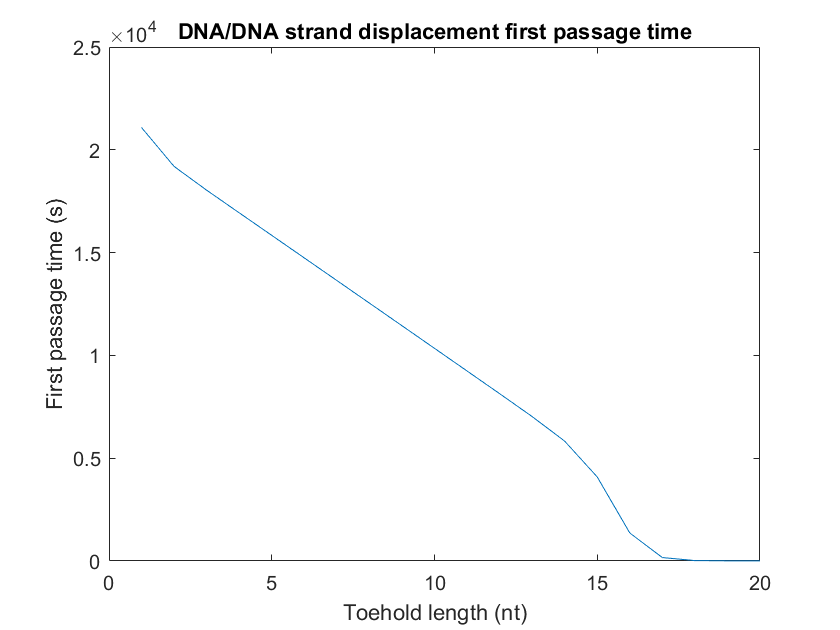

plot(1:20, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

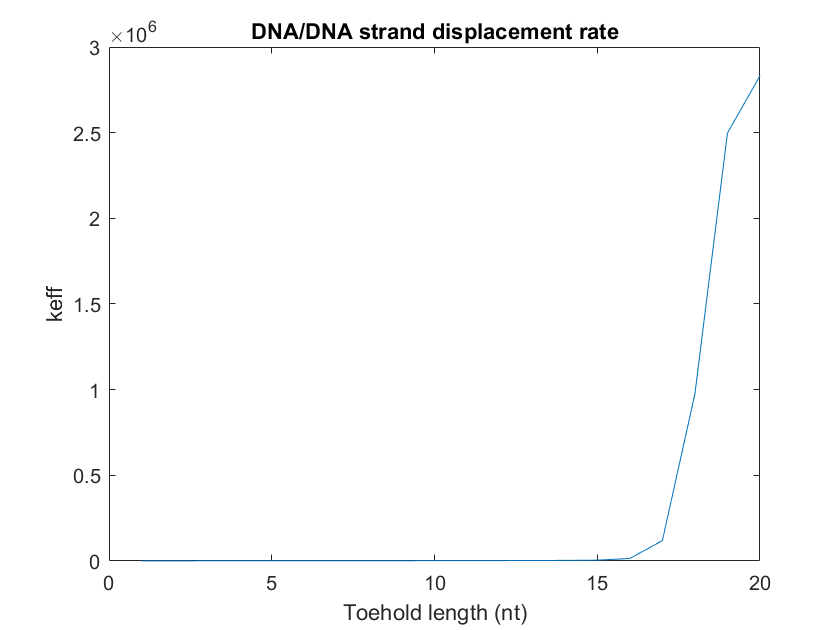


plot(1:20, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

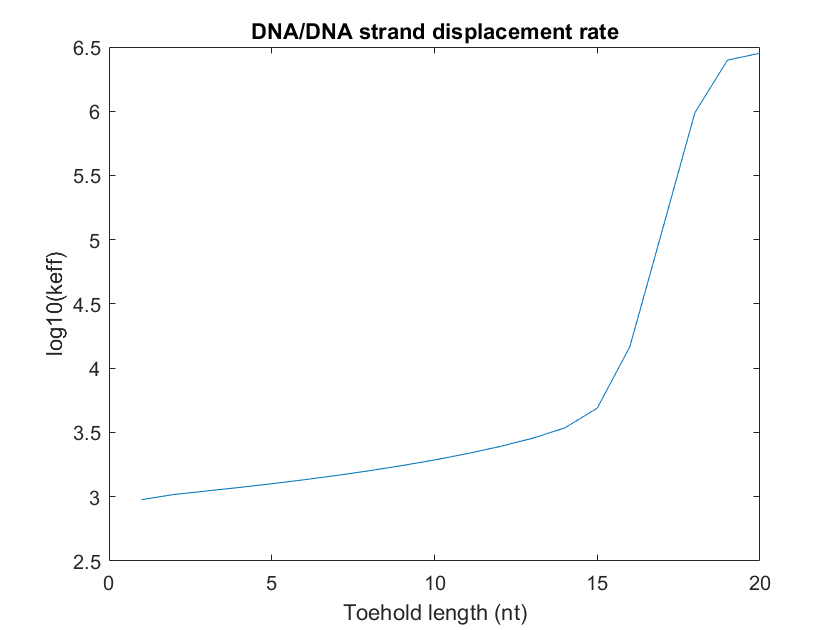


plot(1:20, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate') 

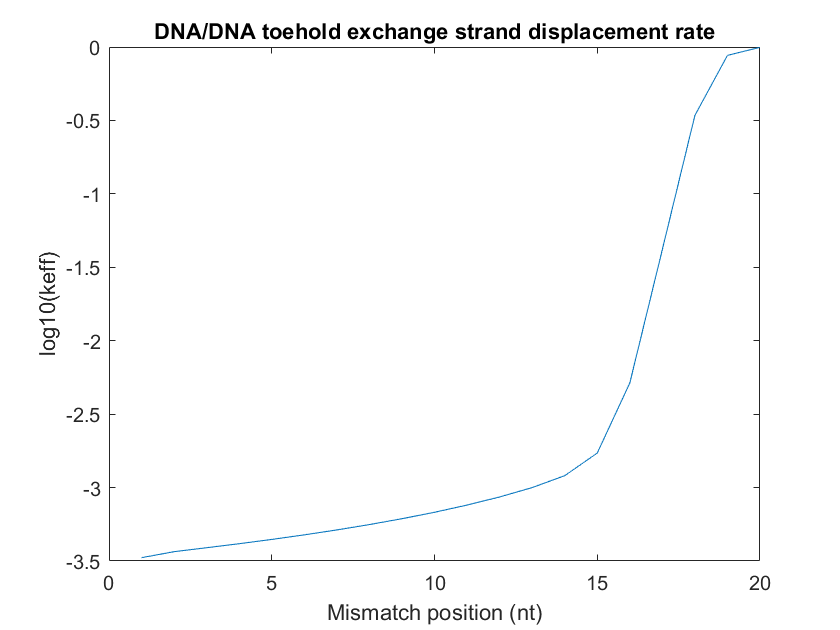


plot(1:20, log10(k_eff./k_eff_perf))
xlabel('Mismatch position (nt)')
ylabel('log10(keff)')
title('DNA/DNA toehold exchange strand displacement rate')  